# **Plot Integer Power-Jitter Relation**

**GENERATED BY: YUYANG ZHU**

clear varaible; close all; clc; clear;

## Laplace transform

f = 1e3 : 10e3 : 1e9;
s = 1j .* f .* 2 .* pi;
j = 0.1:1:1000;
% Integrated range of RMS jitter 
Nstart = 1;
Nstop = 10001; % 100MHz
% Nstop = 1001; % 10MHz
% Nstop = 4001; % 40MHz
% Nstop = length(f); % 1GHz

## Constants

k = 1.38e-23;
T = 300;
y = 1; %MOS excess noise coefficient
Q = 10; %VCO quality factor

Fref = 50e6;
f2 = Fref/10;
Sref = 1e-16; %Reference Noise
Pvco_lj = k.*T.*(1+y).*Sref ./ ((pi .^2) .* (Q.^2) .* (Fref.^2) .* ((j.*1e-15).^4));
Pvco_hj = k.* T .* (1+y) ./((pi .* Q.^2 .*f2 .*((j.*1e-15).^2 - (0.1 .* Sref ./ 4 ./ pi./Fref))));
for i =1:1:1000
    if i <= 180
        Pvco(i) = Pvco_lj(i);
    else
        Pvco(i) = Pvco_hj(i);
    end
end


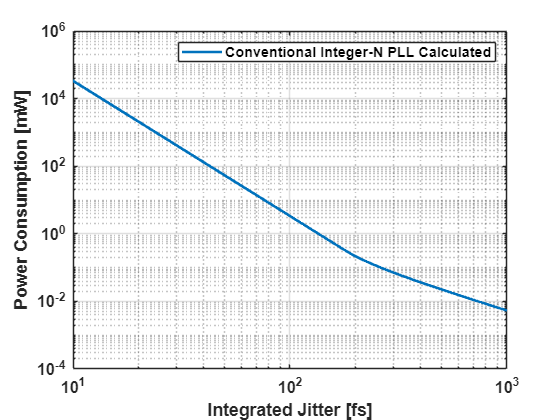

figure()
%loglog(j, Pvco_lj*1e3,j,Pvco_hj*1e3,j,Pvco*1e3,'LineWidth',2);
loglog(j,Pvco*1e3,'LineWidth',2);
set(gca, 'FontName', 'Arial', 'fontsize', 12, 'fontweight', 'b');
axis ([10 1e3 1e-4 1e6]);
grid on;
legend ('Conventional Integer-N PLL Calculated');
xlabel('Integrated Jitter [fs]');
ylabel('Power Consumption [mW]');

%title('Main Loop Transfer Function');